# Lab 6 by Cole Bardin Section 62

## Homogeneous Coordinates: Geometric Transformations, Tessellations

## Question 1

clc, clear, close all

T5n5 = translate(5,-5)*[15;25;1]

T5n5 =     20
    20
     1


## Questions 2-4

clc, clear, close all

% a)
tile1 = [0 2 2 0; % vertex points for the tile in homogeneous coordinates
    0 0 1 1;
    1 1 1 1]

tile1 =      0     2     2     0
     0     0     1     1
     1     1     1     1


x = tile1(1,:); % x coordinates for the tile are in row 1
y = tile1(2,:); % y coordinates for the tile are in row 2
figure
fill(x, y, 'cyan')
grid on
hold on
axis equal tight
axis([-10 10 -10 10])
set(gca, 'FontSize', 16)

% b)
% These two vectors span the entire plane.
v1 = [2, 0]

v1 =      2     0


v2 = [1, 1]

v2 =      1     1


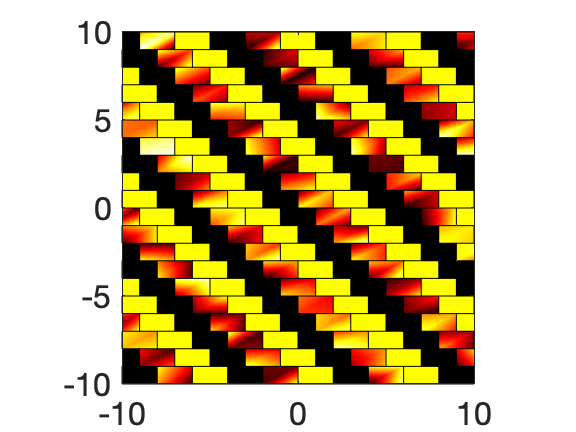


% c)
% Translate the first tile by v1.
dx = v1(1); dy = v1(2);
next_tile = translate(dx, dy) * tile1;
x = next_tile(1,:); y = next_tile(2,:); % Get the x and y coordinates
fill(x, y, 'blue') % plot the next_tile in blue

% d)
% Translate the first tile by v2.
dx = v2(1); dy = v2(2);
next_tile = translate(dx, dy) * tile1;
x = next_tile(1,:); y = next_tile(2,:); % Get the x and y coordinates
fill(x, y, 'yellow') % plot the next_tile in blue

% e)
% Use nested for loops to tessellate the entire plane.
colormap hot;
for m = -10:10
    for n = -10:10
        % add code here!!
        v = m*v1 + n*v2;
        dx = v(1); dy = v(2);
        next_tile = translate(dx,dy) * tile1;
        x = next_tile(1,:); y = next_tile(2,:);
        % Alternate colors between red, yellow and black
        if mod(m+n,3)==0
            C = rand(size(x));
            fill(x, y, C) % Fill using bilinear interpolation. 
            % Add code to fill using 'red'
            %fill(x,y,'red')
        elseif mod(m+n,3)==1
            % Add code to fill using 'yellow'
            fill(x,y,'yellow')
        else
            % Add code to fill using 'black'
            fill(x,y,'black')
        end
        pause(0.05) % Animates the tessellation
    end
end

## Questions 5-7

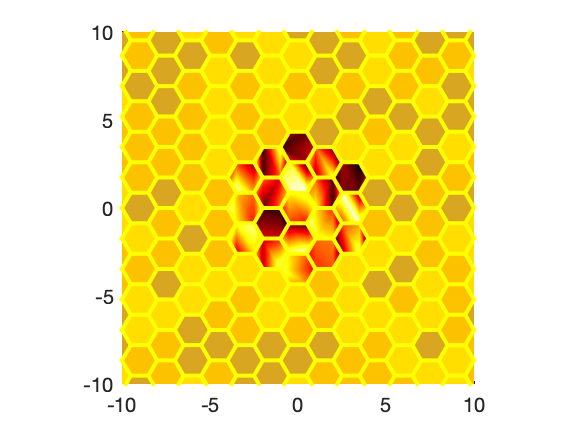

% a)
clear, clc, close all
r = 1; % radius of the hexagonal cell
% Pre-initialize each vector to hold coordinates for the six points of the
% hexagonal bee cell.
x = ones(1,6); % temporary values
y = ones(1,6); % temporary values
z = ones(1,6); % homogeneous third coordinate
for k = 1:6
    x(k) = r * cos(k*pi/3); y(k) = r * sin(k*pi/3);
end
figure
%fill(x, y, 'yellow')

% b)
%fill(x, y, colors('goldenrod'))

% c)
axis equal tight
hold on
xlim([-10,10]);
ylim([-10,10]);

% d)
fill(x, y, colors('goldenrod'), 'EdgeColor','yellow', 'LineWidth', 2)

% e)
% These two vectors span the entire honeycomb.
v1 = [1+cos(pi/3),sin(pi/3)]; % Shifts cell to the north-east
v2 = [1+cos(pi/3),-sin(pi/3)]; % Shifts cell to the south-east

cell1 = [x; y; z]; % homogeneous form with third component = 1

% f)
dx = v1(1); dy = v1(2);
new_cell = translate(dx, dy) * cell1;
x = new_cell(1,:); y = new_cell(2,:);
fill(x,y, colors('golden poppy'), 'EdgeColor','yellow', 'LineWidth', 2)

% g)
dx = v2(1); dy = v2(2);
new_cell = translate(dx, dy) * cell1;
x = new_cell(1,:); y = new_cell(2,:);
fill(x,y, colors('golden yellow'), 'EdgeColor','yellow', 'LineWidth', 2)

% h)
color_choice = [colors('goldenrod'); colors('golden poppy'); colors('golden yellow') ];

colormap hot;
for m = -10:10
    for n = -10:10
        % Add code here.
        v = m*v1 + n*v2;
        dx = v(1); dy = v(2);
        new_cell = translate(dx, dy) * cell1;
        x = new_cell(1,:); y = new_cell(2,:);
        next_color = color_choice(randi([1 3]), :);
        if norm(v) < 4
            next_color = rand(size(x));
        end
        fill(x,y, next_color, 'EdgeColor','yellow', 'LineWidth', 2)
        pause(0.025) % Animates the honeycomb tessellation
    end
end

## Question 8

Z = rotate(30) * [20; 21; 1]; z = Z(1:2) % grab just the first two components

z =     6.8205
   28.1865


n = norm(z) 

n = 29

## Question 9

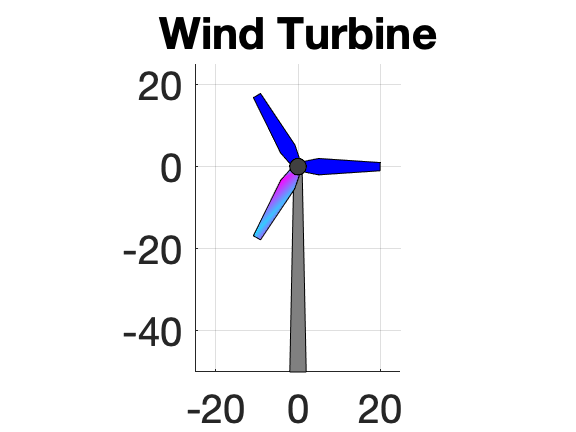

clear, clc, close all
figure(9)
title('Wind Turbine')
hold on
pole = [ -2, 2, 1, -1;-50 -50, 0, 0];
x = pole(1, :); y = pole(2, :);
fill(x, y, [0.5, 0.5, 0.5]); % dark grey
blade1 = [0, 5, 20, 20, 5, 0;-1, -2, -1, 1, 2, 1;1, 1, 1, 1, 1, 1];

x = blade1(1, :); y = blade1(2, :);
h1 = fill(x, y, "blue");
% rotate blade1 by 120 degrees to create blade2. Draw it!
blade2 = rotate(120)*blade1;
x = blade2(1, :); y = blade2(2, :);
h2 = fill(x, y, "blue");
% rotate blade2 by 120 degrees to create blade3. Draw it!
blade3 = rotate(120)*blade2;
x = blade3(1, :); y = blade3(2, :);
h3 = fill(x, y, "blue");
hub = circle(0, 0, 2); % draw the hub
axis equal
axis([-25, 25, -50, 25])
grid on
set(gca, 'fontsize', 20)
% Question 10
% 10. Animate the wind turbine! Make it spin!!
N = 10; % ten complete revolutions
delta = 5; % degrees

colormap cool;

for k = 1 : 72*N
    % delete the previous position of each blade and the old hub
    delete(hub)
    % delete h1, h2 and h3 here
    delete(h1)
    delete(h2)
    delete(h3)
    % rotate each blade by delta
    blade1 = rotate(delta)*blade1;
    blade2 = rotate(delta)*blade2;
    blade3 = rotate(delta)*blade3;
    % redefine blade1, blade2 and blade3 here – rotate each by delta
    
    % draw all three blades using fill. Use the handles h1, h2 and h3 as before
    x = blade1(1, :); y = blade1(2, :);
    h1 = fill(x, y, "blue");
    x = blade2(1, :); y = blade2(2, :);
    h2 = fill(x, y, "blue");
    x = blade3(1, :); y = blade3(2, :);
    C = rand(size(x)); % For fun, color third blade bilinear interpolation
    h3 = fill(x, y, C);
    % draw the hub again
    hub = circle(0, 0, 2);
    pause(0.025)
end

%% Circle Function

function h = circle(x,y,r)
    hold on
    theta = 0:pi/50:2*pi;
    xunit = r * cos(theta) + x;
    yunit = r * sin(theta) + y;
    h = fill(xunit, yunit, [0.25 0.25 0.25]); % dark grey color
end

%% Rotate Function
function [ T ] = rotate(angle_in_deg)
    T = [dcos(angle_in_deg), -dsin(angle_in_deg), 0; dsin(angle_in_deg), dcos(angle_in_deg), 0; 0,0,1];
end
%% Translate Function
function [ T ] = translate( dx, dy )
     % Returns a matrix T to translate a 2d vector, represented in homogeneous
     % coordinates by dx and dy.
     % Define T here. Be sure to terminate with a semicolon.
     T = [1,0,dx;0,1,dy;0,0,1];
end